% Import cell architecture library with all parameters and models.
clc; clear all; close all;
CellArchLib.createLib();

Unit Cell Architecture Library created successfully.


% Check cell architecture library with all parameters and models.
clc; clear all; close all;
load('Unit Cell Architecture.mat');
cellArchLib.disp();

CellArchLib containing:
S/N:        1
Name:       SC
Cell Type:  Strut
# Nodes:    1
# Struts:   3
Max Degree: 6
Min Degree: 6
c2s Factor: 1.00000

S/N:        2
Name:       BCC
Cell Type:  Strut
# Nodes:    2
# Struts:   8
Max Degree: 8
Min Degree: 8
c2s Factor: 0.86603

S/N:        3
Name:       FCC
Cell Type:  Strut
# Nodes:    4
# Struts:   12
Max Degree: 12
Min Degree: 4
c2s Factor: 0.70711

S/N:        4
Name:       BCC+FCC
Cell Type:  Strut
# Nodes:    5
# Struts:   20
Max Degree: 20
Min Degree: 4
c2s Factor: 0.74684

S/N:        5
Name:       Octet
Cell Type:  Strut
# Nodes:    4
# Struts:   24
Max Degree: 12
Min Degree: 12
c2s Factor: 0.70711

S/N:        6
Name:       Kelvin Cell
Cell Type:  Strut
# Nodes:    12
# Struts:   24
Max Degree: 4
Min Degree: 4
c2s Factor: 0.35355

S/N:        7
Name:       Rhombic Dodecahedron
Cell Type:  Strut
# Nodes:    12
# Struts:   32
Max Degree: 8
Min Degree: 4
c2s Factor: 0.43301



% Check methods in CellArchLib
cellArchLib.findCellArch("SC")

ans = S/N:		 1
Name:		 SC
Cell Type:	 Strut
# Nodes:	 1
# Struts:	 3
Max Degree: 6
Min Degree: 6
c2s Factor: 1.00000


cellArchLib.findCellArch("BCC+FCC")

ans = S/N:		 4
Name:		 BCC+FCC
Cell Type:	 Strut
# Nodes:	 5
# Struts:	 20
Max Degree: 20
Min Degree: 4
c2s Factor: 0.74684


cellArchLib.findCellArch("Octet")

ans = S/N:		 5
Name:		 Octet
Cell Type:	 Strut
# Nodes:	 4
# Struts:	 24
Max Degree: 12
Min Degree: 12
c2s Factor: 0.70711


cellArchLib.findCellArch("Rhombic")


ans =

     []



cellArchLib.findCellArch("Rhombic Dodecahedron")

ans = S/N:		 7
Name:		 Rhombic Dodecahedron
Cell Type:	 Strut
# Nodes:	 12
# Struts:	 32
Max Degree: 8
Min Degree: 4
c2s Factor: 0.43301


clc; clear all; close all;
load('Strut Lattice.mat');

% Create UnitCellStrut objects
num_cases = 0;
for idx_cell = 1:length(unit_cell)
	for idx_length = 1:length(cell_length)
		for idx_density = 1:length(rel_density)
			num_cases = num_cases + 1;
			ExptCases{num_cases,:} = ...
                UnitCellStrut(unit_cell(idx_cell),cell_length(idx_length),rel_density(idx_density));
		end
	end
end
save('Experiment Unit Cells.mat','unit_cell','cell_length','rel_density','ExptCases');

clear all; clc;
load('Experiment Unit Cells.mat');
% Check UnitCell objects.
cases = [1 5 12 21 35 48 56 84];
for idx = cases
	disp(ExptCases{idx,:});
end

S/N:		1
Name:		SC
Cell Length:	4.00000
Rel Density:	0.10000
Strut Length:	4.00000
Strut Width:	0.87490

S/N:		1
Name:		SC
Cell Length:	6.00000
Rel Density:	0.10000
Strut Length:	6.00000
Strut Width:	1.31235

S/N:		1
Name:		SC
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	8.00000
Strut Width:	3.90653

S/N:		2
Name:		BCC
Cell Length:	8.00000
Rel Density:	0.10000
Strut Length:	6.92820
Strut Width:	1.15074

S/N:		3
Name:		FCC
Cell Length:	8.00000
Rel Density:	0.30000
Strut Length:	5.65685
Strut Width:	1.97118

S/N:		4
Name:		BCC+FCC
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	5.97469
Strut Width:	1.73082

S/N:		5
Name:		Octet
Cell Length:	6.00000
Rel Density:	0.40000
Strut Length:	4.24264
Strut Width:	1.23602

S/N:		7
Name:		Rhombic Dodecahedron
Cell Length:	8.00000
Rel Density:	0.40000
Strut Length:	3.46410
Strut Width:	1.83837



clc; clear all; close all;
load('Strut Lattice.mat');
section = "Circular";

freq = 100:10:6300;
% Create StrutLattLayer objects
num_cases = 0;
for idx_cell = 1:length(unit_cell)
	for idx_length = 1:length(cell_length)
		for idx_density = 1:length(rel_density)
			num_cases = num_cases + 1;
			labels(:,num_cases) = strcat(unit_cell(idx_cell),sprintf("; L=%dmm; RD=%.1f", ...
				cell_length(idx_length),rel_density(idx_density)));
            part = LattLayerStrut(unit_cell(idx_cell), ...
                cell_length(idx_length),rel_density(idx_density), ...
                section,30,30,24/cell_length(idx_length));
            layer = LattLayer(section,freq);
            layer.insertPart(part,1);
            ExptCases{num_cases,:} = layer;
		end
	end
end
save('Experiment Unit Cell Layers.mat','labels','unit_cell','cell_length','rel_density','ExptCases');

clc; clear all; close all;
load('Experiment Unit Cell Layers.mat');
% Check UnitCell objects.
cases = [3 10 17 24 31 39 45 55 69 81];
for idx = cases
	disp(ExptCases{idx,:});
end

Lattice Layer containing:
Number:		1
Name:          SC
Cell Length:   4.00000
Rel Density:   0.30000
Strut Length:  4.00000
Strut Width:   1.65340
Cross Section: Circular
# layers:      6
Surface Ratio: 1.0


Lattice Layer containing:
Number:		1
Name:          SC
Cell Length:   8.00000
Rel Density:   0.20000
Strut Length:  8.00000
Strut Width:   2.61450
Cross Section: Circular
# layers:      3
Surface Ratio: 1.0


Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   6.00000
Rel Density:   0.10000
Strut Length:  5.19615
Strut Width:   0.86305
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0


Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   8.00000
Rel Density:   0.40000
Strut Length:  6.92820
Strut Width:   2.56134
Cross Section: Circular
# layers:      3
Surface Ratio: 1.0


Lattice Layer containing:
Number:		1
Name:          FCC
Cell Length:   6.00000
Rel Density:   0.30000
Strut Length:  4.24264
Strut Width:   1.47838
Cross Section:

clc; clear all; close all;
load('Experiment Unit Cell Layers.mat');
load('Strut Lattice.mat','freq');
sample = Lattice('Circle',freq(:,1));
insertLayer(sample,ExptCases{10},1);
insertLayer(sample,ExptCases{20},2);
insertLayer(sample,ExptCases{30},3);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          SC
Cell Length:   8.00000
Rel Density:   0.20000
Strut Length:  8.00000
Strut Width:   2.61450
Cross Section: Circular
# layers:      3
Surface Ratio: 1.0



Number:		2
Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   6.00000
Rel Density:   0.40000
Strut Length:  5.19615
Strut Width:   1.92101
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0



Number:		3
Lattice Layer containing:
Number:		1
Name:          FCC
Cell Length:   6.00000
Rel Density:   0.20000
Strut Length:  4.24264
Strut Width:   1.16856
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0




sample.t_sample

ans = 72

removeLayer(sample,1);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   6.00000
Rel Density:   0.40000
Strut Length:  5.19615
Strut Width:   1.92101
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0



Number:		2
Lattice Layer containing:
Number:		1
Name:          FCC
Cell Length:   6.00000
Rel Density:   0.20000
Strut Length:  4.24264
Strut Width:   1.16856
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0




removeLayer(sample,2);
sample

sample = Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   6.00000
Rel Density:   0.40000
Strut Length:  5.19615
Strut Width:   1.92101
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0




sample.updateThickness(1);
calcTMM(sample);
calcSAC(sample);

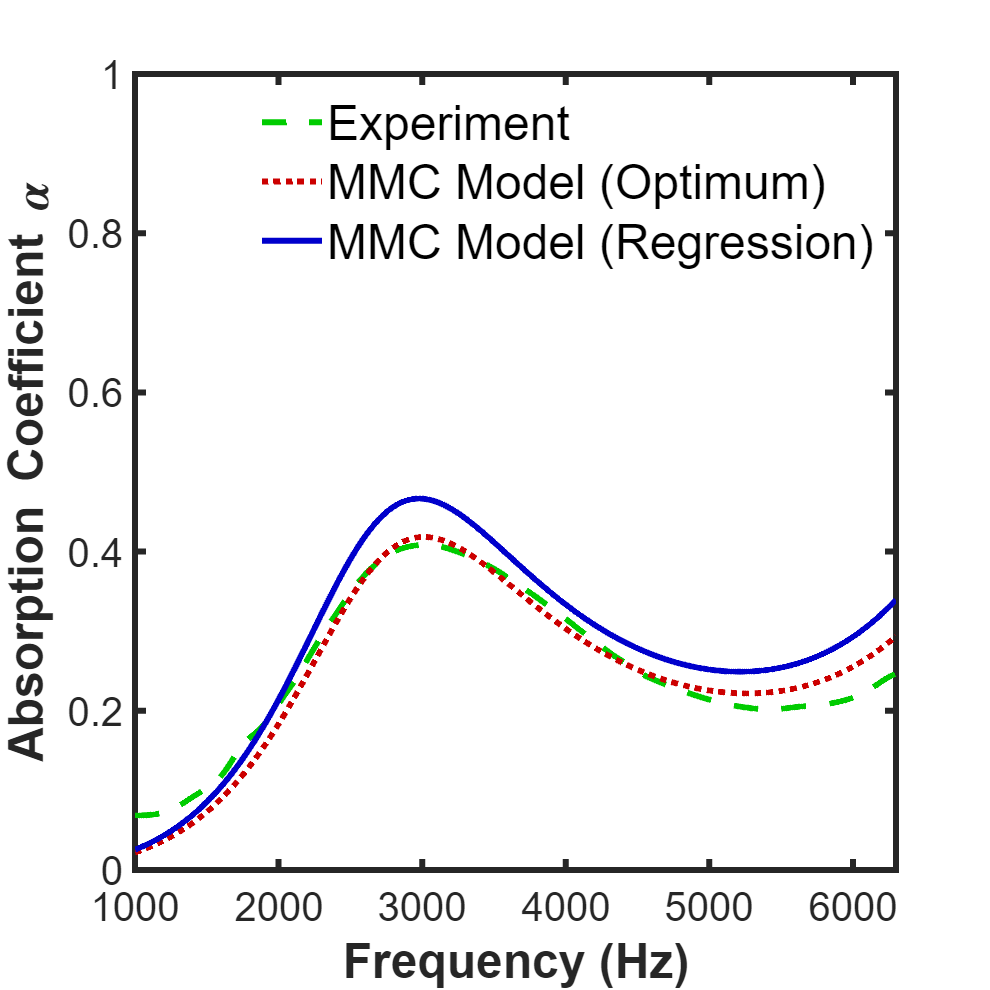

clc; clear all; close all;
load('Strut Lattice.mat');
load('Experiment Unit Cell Layers.mat');

figure('Position', [100 100 660 660]);
color = [0 0.8 0;0.8 0 0;0 0 0.8;0.8 0.6 0];
line_style = ["--" ":" "-" "-."];
marker = ['o','+','x','s'];

for case_no = 1:length(labels)
    f = freq(:,case_no);
	alpha_expt = SAC_expt(:,case_no);
	label = labels(case_no);
	
	% Experiment
	plot(freq(:,case_no),SAC_expt(:,case_no),'DisplayName','Experiment', ...
		'Color',color(1,:),'LineStyle',line_style(1),'LineWidth',3);
	hold on;
	
	% MMC Model (Initial)
	idx_cell = case_idx(case_no,2);
	idx_length = case_idx(case_no,3);
	idx_density = case_idx(case_no,4);
	N_layer = 24/cell_length(idx_length);
    
	% From optimization.
	str_length = strut_length(length(rel_density)*(idx_length-1)+idx_density,idx_cell)*1e-3 * length_corr_best(idx_cell,1);
	str_width = strut_width(length(rel_density)*(idx_length-1)+idx_density,idx_cell)*1e-3 * width_corr_best(idx_cell,1);
	delta_1 = delta_1_best(length(rel_density)*(idx_length-1)+idx_density,idx_cell);
	delta_2 = delta_2_best(length(rel_density)*(idx_length-1)+idx_density,idx_cell);
	
	alpha_MMC = MMC_strut(str_length,str_width,N_layer,delta_1,delta_2,f);
	plot(freq(:,case_no),alpha_MMC,'DisplayName','MMC Model (Optimum)', ...
		'Color',color(2,:),'LineStyle',line_style(2),'LineWidth',3);
	hold on;
	error_MMC_optimum(length(rel_density)*(idx_length-1)+idx_density,idx_cell) = mean(abs(alpha_expt-alpha_MMC));
    
    % From Regression Models.
    sample = Lattice('Circle',freq(:,case_no));
    insertLayer(sample,ExptCases{case_no},1);
    calcTMM(sample);
    calcSAC(sample);
    alpha_MMC = sample.SAC;
	plot(freq(:,case_no),alpha_MMC,'DisplayName','MMC Model (Regression)', ...
		'Color',color(3,:),'LineStyle',line_style(3),'LineWidth',3);
	hold on;
	error_MMC_NN(length(rel_density)*(idx_length-1)+idx_density,idx_cell) = mean(abs(alpha_expt-alpha_MMC));

    ax = gca;
	ax.FontSize = 20;
	ax.XLim = [1000 6300];
	ax.YLim = [0 1];
	ax.XTick = 1000:1000:6300;
	ax.YTick = 0:0.2:1.0;
	ax.XLabel.String = "Frequency (Hz)";
	ax.YLabel.String = "Absorption Coefficient \alpha";
	ax.XLabel.FontSize = 24;
    ax.YLabel.FontSize = 24;
    ax.XLabel.FontWeight = 'bold';
    ax.YLabel.FontWeight = 'bold';
    ax.Box = 'on';
    ax.LineWidth = 3;
	legend('Location','northeast','NumColumns',1);
	legend('FontSize',24);
	legend('boxoff');
	
	print(strcat('MMC-',label,'.tif'),'-dtiff','-r500');
	hold off;

    removeLayer(sample,1);
end

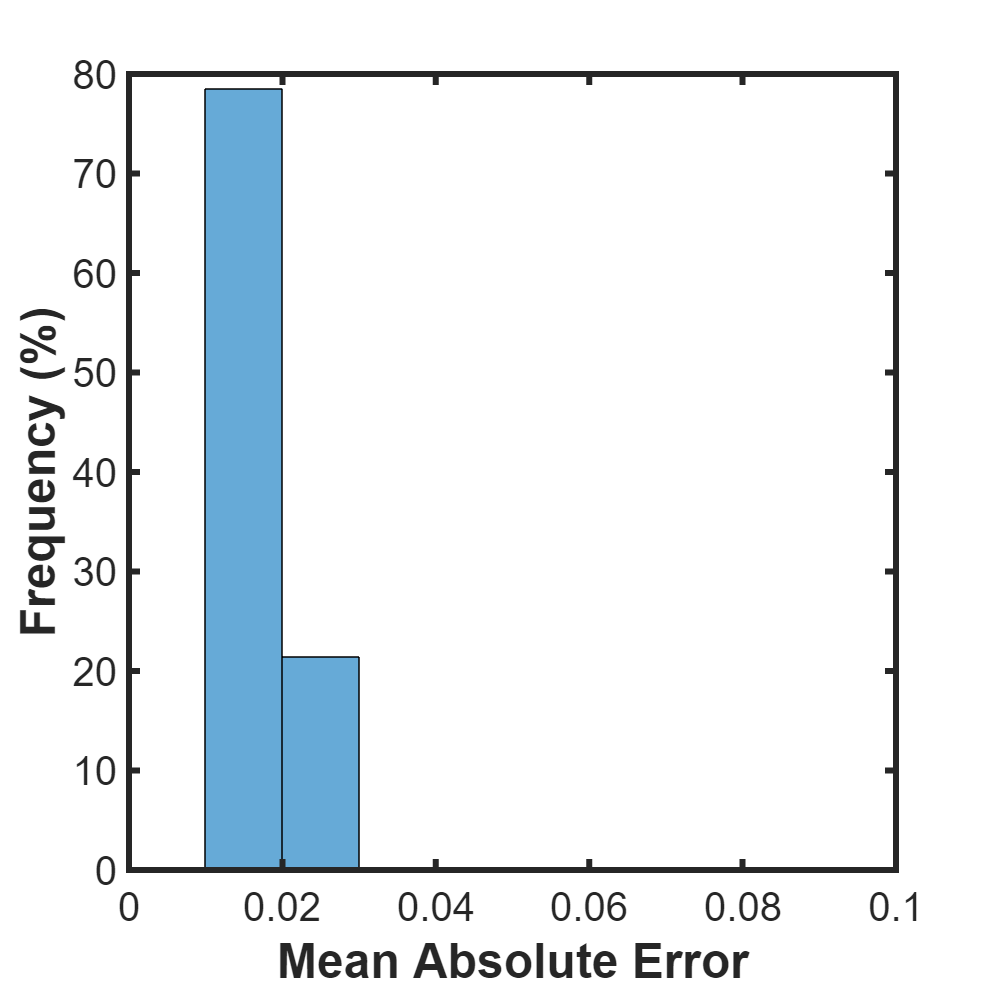

% Plot of Errors
figure('Position', [100 100 660 660]);
x_pdf = [0:1:10]./100;
histogram(reshape(error_MMC_optimum,[],1),x_pdf,'Normalization','pdf');
hold on;

ax = gca;
ax.FontSize = 20;
ax.XLim = [0 10]./100;
ax.XTick = [0:2:10]./100;
ax.YLim = [0 80];
ax.YTick = 0:10:80;
ax.XLabel.String = "Mean Absolute Error";
ax.YLabel.String = "Frequency (%)";
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';
ax.Box = 'on';
ax.LineWidth = 3;

% Saves graph as .png file. Open them up to see.
print("error_MMC_optimum.tif",'-dtiff','-r500');
hold off;

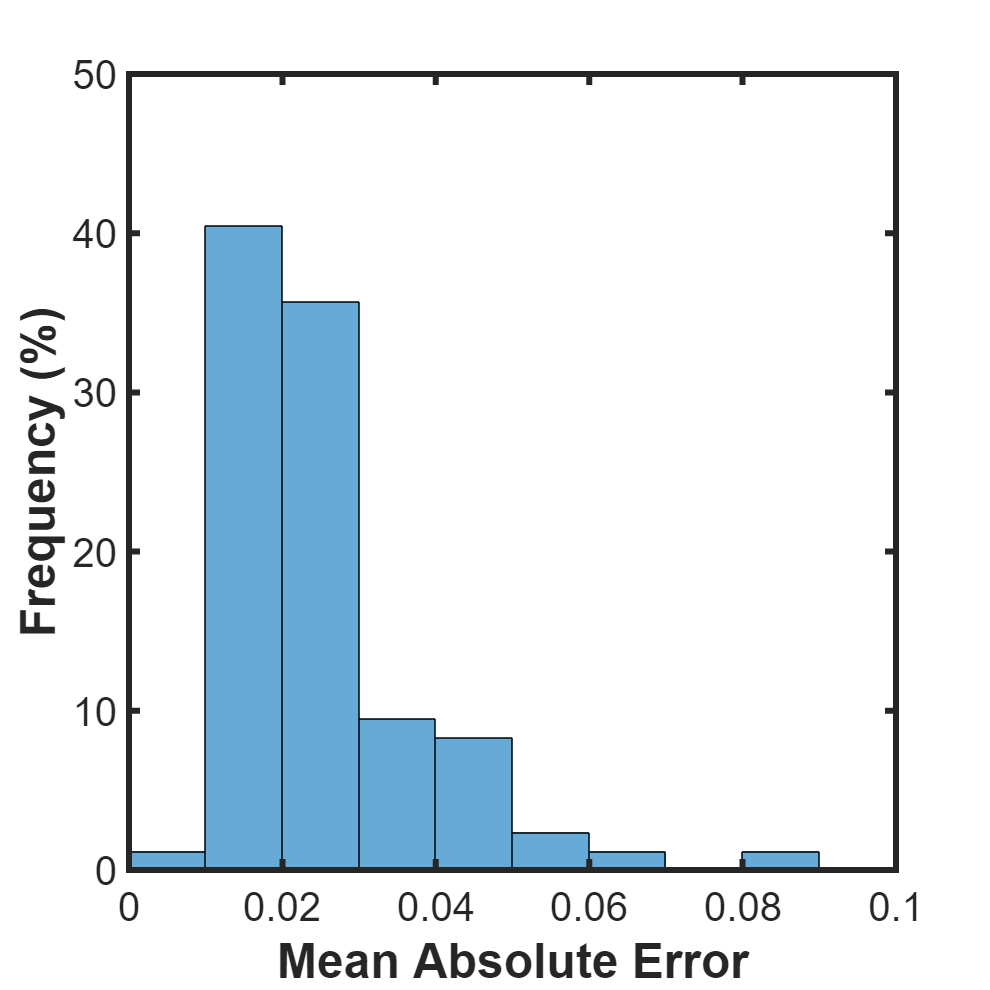


%pause;

figure('Position', [100 100 660 660]);
x_pdf = [0:1:10]./100;
histogram(reshape(error_MMC_NN,[],1),x_pdf,'Normalization','pdf');
hold on;

ax = gca;
ax.FontSize = 20;
ax.XLim = [0 10]./100;
ax.XTick = [0:2:10]./100;
ax.YLim = [0 50];
ax.YTick = 0:10:50;
ax.XLabel.String = "Mean Absolute Error";
ax.YLabel.String = "Frequency (%)";
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';
ax.Box = 'on';
ax.LineWidth = 3;

% Saves graph as .png file. Open them up to see.
print("error_MMC_NN.tif",'-dtiff','-r500');
hold off;

% Create LatticeLibrary
clc; clear all; close all;
LatticeLib.createLib();

Lattice Library created successfully.


% Sample validation cases.
clc; clear all; close all;
load('Strut Lattice.mat','unit_cell');
section = "Circular";
frequency = 100:10:6300;

cell_length = 4:0.5:8;
rel_density = 0.1:0.05:0.4;
num_samples = 4;
count = 0;

%% 3 layers in series, 1 homogeneous layer, 2 heterogeneous with 2 parts.
for idx_sample = 1:num_samples
    count = count + 1;
    sample{count} = Lattice('Circle',frequency);
    idx_cell = randperm(length(unit_cell),5);
    idx_length = randperm(length(cell_length),5);
    idx_density = randperm(length(rel_density),5);
    layer_type = randperm(3);
    for idx_layer = 1:3
        layer = LattLayer(section,frequency);
        switch layer_type(idx_layer)
            case 1 % Homogeneous
                part = LattLayerStrut(unit_cell(idx_cell(1)), ...
                    cell_length(idx_length(1)), ...
                    rel_density(idx_density(1)), ...
                    section,30,30, ...
                    floor(16/cell_length(idx_length(1))));
                layer.insertPart(part,1);
            case 2 % 2 Parts, each surface ratio 0.5
                for idx_part = 1:2
                    part = LattLayerStrut(unit_cell(idx_cell(idx_part+1)), ...
                        cell_length(idx_length(idx_part+1)), ...
                        rel_density(idx_density(idx_part+1)), ...
                        section,30,30, ...
                        floor(16/cell_length(idx_length(idx_part+1))));
                    layer.insertPart(part,1/2);
                end
            case 3 % 2 Parts, surface ratio random
                SR = randi(9)/10;
                for idx_part = 1:2
                    part = LattLayerStrut(unit_cell(idx_cell(idx_part+3)), ...
                        cell_length(idx_length(idx_part+3)), ...
                        rel_density(idx_density(idx_part+3)), ...
                        section,30,30, ...
                        floor(16/cell_length(idx_length(idx_part+3))));
                    layer.insertPart(part,SR*(idx_part==1)+(1-SR)*(idx_part==2));
                end
        end
        insertLayer(sample{count},layer,idx_layer);
    end
    sample{count}.updateThickness(1);
    calcTMM(sample{count});
    calcSAC(sample{count});
end
% save('Validation.mat','sample');

clc; clear all; close all;
load('Validation.mat');
load('Lattice Library.mat');
for idx_sample = 1:length(sample)
    fprintf('SAMPLE NUMBER %d\n',idx_sample);
    disp(sample{idx_sample})
    LattLib.insert(sample{idx_sample},LattLib.Length+1);
	LattLabel.insert(sprintf('Validation Sample %d',idx_sample),LattLabel.Length+1);
end

SAMPLE NUMBER 1


Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          FCC
Cell Length:   4.00000
Rel Density:   0.35000
Strut Length:  2.82843
Strut Width:   1.07777
Cross Section: Circular
# layers:      4
Surface Ratio: 0.5


Number:		2
Name:          Octet
Cell Length:   6.00000
Rel Density:   0.25000
Strut Length:  4.24264
Strut Width:   0.94015
Cross Section: Circular
# layers:      2
Surface Ratio: 0.5



Number:		2
Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   7.50000
Rel Density:   0.20000
Strut Length:  6.49519
Strut Width:   1.60951
Cross Section: Circular
# layers:      2
Surface Ratio: 0.1


Number:		2
Name:          Rhombic Dodecahedron
Cell Length:   8.00000
Rel Density:   0.10000
Strut Length:  3.46410
Strut Width:   0.81703
Cross Section: Circular
# layers:      2
Surface Ratio: 0.9



Number:		3
Lattice Layer containing:
Number:		1
Name:          BCC+FCC
Cell Length:   7.00000
Rel Density:   0.40000
Strut Length:  5.22786
Strut Wid

SAMPLE NUMBER 2


Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          Rhombic Dodecahedron
Cell Length:   5.50000
Rel Density:   0.40000
Strut Length:  2.38157
Strut Width:   1.26388
Cross Section: Circular
# layers:      2
Surface Ratio: 0.2


Number:		2
Name:          SC
Cell Length:   4.00000
Rel Density:   0.10000
Strut Length:  4.00000
Strut Width:   0.87490
Cross Section: Circular
# layers:      3
Surface Ratio: 0.8



Number:		2
Lattice Layer containing:
Number:		1
Name:          Octet
Cell Length:   7.50000
Rel Density:   0.30000
Strut Length:  5.30330
Strut Width:   1.30678
Cross Section: Circular
# layers:      2
Surface Ratio: 1.0



Number:		3
Lattice Layer containing:
Number:		1
Name:          Kelvin Cell
Cell Length:   4.50000
Rel Density:   0.35000
Strut Length:  1.59099
Strut Width:   1.24652
Cross Section: Circular
# layers:      3
Surface Ratio: 0.5


Number:		2
Name:          FCC
Cell Length:   6.00000
Rel Density:   0.25000
Strut Length:  4.24264
Strut 

SAMPLE NUMBER 3


Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          Octet
Cell Length:   4.50000
Rel Density:   0.35000
Strut Length:  3.18198
Strut Width:   0.85768
Cross Section: Circular
# layers:      3
Surface Ratio: 1.0



Number:		2
Lattice Layer containing:
Number:		1
Name:          SC
Cell Length:   8.00000
Rel Density:   0.15000
Strut Length:  8.00000
Strut Width:   2.21312
Cross Section: Circular
# layers:      2
Surface Ratio: 0.8


Number:		2
Name:          Kelvin Cell
Cell Length:   6.00000
Rel Density:   0.20000
Strut Length:  2.12132
Strut Width:   1.18906
Cross Section: Circular
# layers:      2
Surface Ratio: 0.2



Number:		3
Lattice Layer containing:
Number:		1
Name:          Rhombic Dodecahedron
Cell Length:   7.50000
Rel Density:   0.10000
Strut Length:  3.24760
Strut Width:   0.76597
Cross Section: Circular
# layers:      2
Surface Ratio: 0.5


Number:		2
Name:          FCC
Cell Length:   5.00000
Rel Density:   0.40000
Strut Length:  3.53553
Strut 

SAMPLE NUMBER 4


Lattice containing:
Number:		1
Lattice Layer containing:
Number:		1
Name:          BCC
Cell Length:   4.50000
Rel Density:   0.30000
Strut Length:  3.89711
Strut Width:   1.22033
Cross Section: Circular
# layers:      3
Surface Ratio: 0.2


Number:		2
Name:          SC
Cell Length:   6.50000
Rel Density:   0.35000
Strut Length:  6.50000
Strut Width:   2.93777
Cross Section: Circular
# layers:      2
Surface Ratio: 0.8



Number:		2
Lattice Layer containing:
Number:		1
Name:          Kelvin Cell
Cell Length:   4.00000
Rel Density:   0.10000
Strut Length:  1.41421
Strut Width:   0.52357
Cross Section: Circular
# layers:      4
Surface Ratio: 1.0



Number:		3
Lattice Layer containing:
Number:		1
Name:          FCC
Cell Length:   6.00000
Rel Density:   0.25000
Strut Length:  4.24264
Strut Width:   1.33003
Cross Section: Circular
# layers:      2
Surface Ratio: 0.5


Number:		2
Name:          Octet
Cell Length:   5.50000
Rel Density:   0.20000
Strut Length:  3.88909
Strut Width:   0.75682


save('Lattice Library.mat','LattLib','LattLabel');
save('Lattice Library - Backup.mat','LattLib','LattLabel');